% Exercise 1: Simulation of the probability that athletes took drugs given
% a positive test result

%  Lets do the simulation 1000 times

% First I need two 1000 by 100 ar
% ray to simulate athletes taking drugs, and
% their tests

athletes_drugs = zeros(1000,100)
athletes_tests = zeros(1000,100)
athletes_tests2 = zeros(1000,100)

druggy_rate = 2 % Proportion of druggies
sensitivity = 9 % Proportion of druggies who received a positive result
specificity = 7 % Proportion of nondruggies who received a negative result

for i = 1:1000
    for j = 1:100 
        athletes_drugs(i,j) = randi(10); 
        athletes_tests(i,j) = randi(10);
        athletes_tests2(i,j) = randi(10);
    end
end

false_positive = zeros(1000,1)
true_positive = zeros(1000,1) 

for i = 1:1000
    for j = 1:100
        
        % took drugs and was detected
        if athletes_tests(i,j) <= sensitivity && athletes_tests2(i,j) <= sensitivity && athletes_drugs(i,j) <= druggy_rate 
            true_positive(i,1) = true_positive(i,1) + 1;
        
            % clean but test detects drugs
        elseif athletes_tests(i,j) > specificity &&  athletes_tests2(i,j) > specificity && athletes_drugs(i,j) > druggy_rate 
            false_positive(i,1) = false_positive(i,1) + 1;

        end

    end
end

% Calculate probability that athlete took drugs given that a test detected
% it
probability = zeros(1000,1)
probability =  true_positive ./ (false_positive + true_positive)

average_prob = mean(probability)

% Plot histogram
histogram(probability, 5, "BinLimits",[0,1])

% --------------------------------------------------------
% Task 2: Probability Distributions
% Choose a discrete and continuous distribution
% Student T and Geometric

% Student's T distribution
x = linspace(10,50,100)

x =    10.0000   10.4040   10.8081   11.2121   11.6162   12.0202   12.4242   12.8283   13.2323   13.6364   14.0404   14.4444   14.8485   15.2525   15.6566   16.0606   16.4646   16.8687   17.2727   17.6768   18.0808   18.4848   18.8889   19.2929   19.6970   20.1010   20.5051   20.9091   21.3131   21.7172   22.1212   22.5253   22.9293   23.3333   23.7374   24.1414   24.5455   24.9495   25.3535   25.7576   26.1616   26.5657   26.9697   27.3737   27.7778   28.1818   28.5859   28.9899   29.3939   29.7980


% Plot pmf's and cmf's

% tpdf and tcdf calculate assuming mean=0, std=1
% So you need to transform samples
x_m = (x - m)/ std

x_m =    -4.0000   -3.9192   -3.8384   -3.7576   -3.6768   -3.5960   -3.5152   -3.4343   -3.3535   -3.2727   -3.1919   -3.1111   -3.0303   -2.9495   -2.8687   -2.7879   -2.7071   -2.6263   -2.5455   -2.4646   -2.3838   -2.3030   -2.2222   -2.1414   -2.0606   -1.9798   -1.8990   -1.8182   -1.7374   -1.6566   -1.5758   -1.4949   -1.4141   -1.3333   -1.2525   -1.1717   -1.0909   -1.0101   -0.9293   -0.8485   -0.7677   -0.6869   -0.6061   -0.5253   -0.4444   -0.3636   -0.2828   -0.2020   -0.1212   -0.0404



student_pdf = tpdf(x_m,20)

student_pdf =     0.0008    0.0010    0.0012    0.0014    0.0017    0.0021    0.0025    0.0030    0.0036    0.0044    0.0052    0.0062    0.0075    0.0089    0.0106    0.0125    0.0149    0.0176    0.0207    0.0243    0.0285    0.0333    0.0388    0.0451    0.0522    0.0602    0.0691    0.0791    0.0901    0.1021    0.1153    0.1295    0.1448    0.1611    0.1783    0.1962    0.2147    0.2337    0.2528    0.2718    0.2904    0.3084    0.3255    0.3412    0.3554    0.3676    0.3778    0.3856    0.3910    0.3937


student_cdf = tcdf(x_m,20)

student_cdf =     0.0004    0.0004    0.0005    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0023    0.0028    0.0033    0.0040    0.0047    0.0057    0.0068    0.0081    0.0096    0.0114    0.0136    0.0161    0.0190    0.0224    0.0263    0.0308    0.0360    0.0420    0.0488    0.0566    0.0654    0.0753    0.0863    0.0987    0.1124    0.1275    0.1441    0.1623    0.1819    0.2031    0.2258    0.2500    0.2756    0.3026    0.3307    0.3600    0.3901    0.4210    0.4524    0.4841


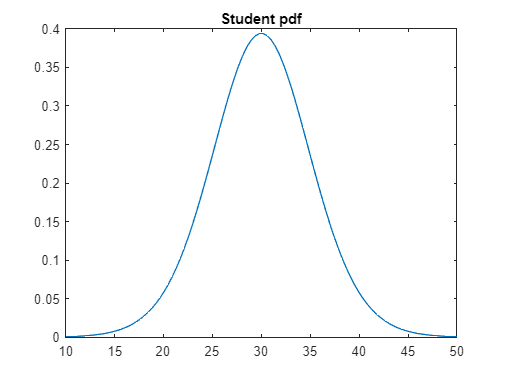


plot(x, student_pdf)
title("Student pdf")

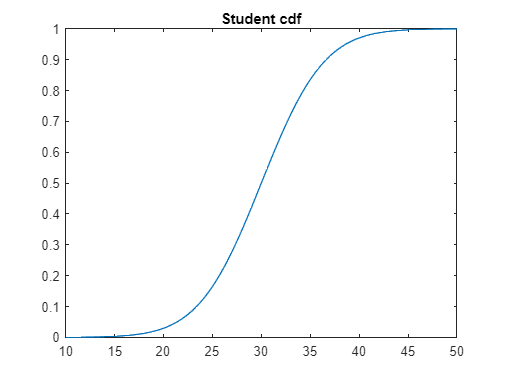



plot(x, student_cdf)
title("Student cdf")

% Geometric Distribution
x = linspace(0,20,101)
p = 0.1
geometric_pdf = geopdf(x,p);
bar(x,geometric_pdf,1)
title("Geometric pdf p = 0.1")

geometric_cdf = geocdf(x,p)
plot(x,geometric_cdf)
title("Geometric cdf p = 0.1")

% Generate 100 samples from each distribution
n = 100

geo_samples = geornd(p, n,1)


std = 5
m = 30

t_samples = trnd(20,n,1) * std + m

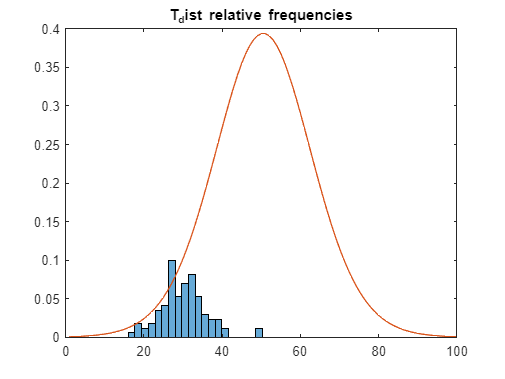

% Generate histograms with relative frequencies

% PROBLEM HERE

histogram(t_samples,20, "Normalization", "pdf")
title("T_dist relative frequencies")
hold on
plot(student_pdf)
hold off


hold off

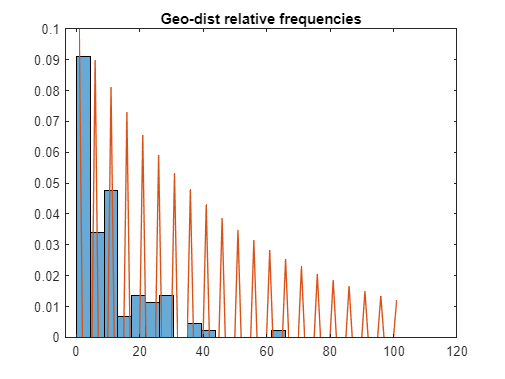


histogram(geo_samples,15,"Normalization","pdf")
title("Geo-dist relative frequencies")
hold on
plot(geometric_pdf)
hold off